# Calcalate matched generators' features in NYCA 2019

The program is used to calculate generation features of the aggregated units in NYAM, such as max power,. min power, and max ramp rate.

## Import the RGGI generation data

% Import hourly generation data of generators in RGGI database in the 2019 whole year
genFileDir = "D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\EPA_AMPD\2019\";
genFileName = "emission*.csv";
genDataStore = fileDatastore(genFileDir + genFileName, "ReadFcn", @importGenerationData, "UniformRead", true);
genAll = readall(genDataStore);
clear genDataStore;

## Import RGGI to NYCA reference table

% Import the reference table from RGGI to NYISO NYCA database
generatorCombiner = importRefTable("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\RGGI2NYCA2019NoAgg.xlsx");

% Create arrays of key features
NYISONames = unique(generatorCombiner.NYISOName);
PTIDs = unique(generatorCombiner.PTID);
unitTypes = unique(generatorCombiner.UnitType);
fuelTypes = unique(generatorCombiner.FuelType);
Zones = unique(generatorCombiner.Zone);

## Group summary of nameplate capacity in NYCA database

% Group summary of nameplate capacity by unit type and fuel type
unitFuelTypeSummary = groupsummary(generatorCombiner, ["UnitType", "FuelType"] , "sum", ["NamePlateRatingMW", "GrossLoadMWh"]);
total_count = sum(unitFuelTypeSummary.GroupCount);
total_cap = sum(unitFuelTypeSummary.sum_NamePlateRatingMW);
total_gen = sum(unitFuelTypeSummary.sum_GrossLoadMWh);
unitFuelTypeSummary.capPer = unitFuelTypeSummary.sum_NamePlateRatingMW/total_cap;
unitFuelTypeSummary.genPer = unitFuelTypeSummary.sum_GrossLoadMWh/total_gen;
unitFuelTypeSummary.Properties.VariableNames = ["unitType", "fuelType", "Count", "totalCapacity", "totalGeneration", "capPercent", "genPercent"]

unitFuelTypeSummary = 9×7 table
         unitType          fuelType      Count    totalCapacity    totalGeneration    capPercent    genPercent
    __________________    ___________    _____    _____________    _______________    __________    __________

    Combined Cycle        Natural Gas     59          18154           3.718e+07         0.52871        0.79628
    Combustion Turbine    Fuel Oil         8          500.9               21660        0.014588     0.00046388
    Combustion Turbine    Natural Gas     30         1247.8          1.1198e+06        0.036341       0.023983
    Jet Engine            Fuel Oil        11            621               36080        0.018086     0.00077272
    Jet Engine            Kerosene        25         1176.5    

unitTypeSummary = groupsummary(unitFuelTypeSummary, "unitType", "sum", ["Count","totalCapacity", "capPercent", "totalGeneration", "genPercent"]);
unitTypeSummary = removevars(unitTypeSummary, "GroupCount");
unitTypeSummary.Properties.VariableNames = ["unitType", "Count", "totalCapacity", "capPercent", "totalGeneration", "genPercent"]

unitTypeSummary = 4×6 table
         unitType         Count    totalCapacity    capPercent    totalGeneration    genPercent
    __________________    _____    _____________    __________    _______________    __________

    Combined Cycle         59          18154          0.52871        3.718e+07         0.79628 
    Combustion Turbine     38         1748.7         0.050929       1.1414e+06        0.024446 
    Jet Engine             39         1946.4         0.056687       1.9104e+05       0.0040916 
    Steam Turbine          31          12487          0.36368       8.1796e+06         0.17518 


fuelTypeSummary = groupsummary(unitFuelTypeSummary, "fuelType", "sum", ["Count","totalCapacity", "capPercent", "totalGeneration", "genPercent"]);
fuelTypeSummary = removevars(fuelTypeSummary, "GroupCount");
fuelTypeSummary.Properties.VariableNames = ["fuelType", "Count", "totalCapacity", "capPercent", "totalGeneration", "genPercent"]

fuelTypeSummary = 4×6 table
     fuelType      Count    totalCapacity    capPercent    totalGeneration    genPercent
    ___________    _____    _____________    __________    _______________    __________

    Coal              2         810.4         0.023602       4.7214e+05         0.010112
    Fuel Oil         32        7896.5          0.22998       2.8215e+06         0.060428
    Kerosene         25        1176.5         0.034264            26821       0.00057443
    Natural Gas     108         24453          0.71216       4.3371e+07          0.92889


## Combine the generation table with the reference table

% Combine the RGGI database with the NYCA database
% Join tables
genAllJoint = innerjoin(genAll,generatorCombiner,'Keys',{'FacilityName','FacilityID','UnitID'}, 'LeftVariables', {'FacilityName',...
    'FacilityID', 'UnitID', 'Date', 'Hour', 'GrossLoadMW', 'HeatInputMMBtu'}, "RightVariables", {'NYISOName', 'PTID', 'Zone', 'UnitType', 'FuelType', 'Combined'});

## Calculate generation features

% Define arrays to record NYISO generators' parameter
maxPower = zeros(size(NYISONames));
minPower = zeros(size(NYISONames));
maxHeat = zeros(size(NYISONames));
minHeat = zeros(size(NYISONames));
maxRampUp = zeros(size(NYISONames));
maxRampDown = zeros(size(NYISONames));
HeatRateLM = zeros(size(NYISONames, 1), 2);
HeatRateQM = zeros(size(NYISONames, 1), 3);
HeatRateLMR2 = zeros(size(NYISONames));
HeatRateQMR2 = zeros(size(NYISONames));
hourlyGenFilteredTables = cell(size(NYISONames));

for i=1:length(NYISONames)
    % Subset generation table by NYISO name
    genName = NYISONames(i);
    genSet = genAllJoint(genAllJoint.NYISOName == genName, :);
    hourlyGen = groupsummary(genSet, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu"]);
    % Calculate ramp rate
    rampRate = hourlyGen.sum_GrossLoadMW(2:end) - hourlyGen.sum_GrossLoadMW(1:end-1);
    hourlyGen.RampRate = [0; rampRate];
    % Exclude hours with zero generation, also exclude ramp down to zero
    hourlyGenNZ = hourlyGen(hourlyGen.sum_GrossLoadMW > 0, :);
    % Calcualte max output and min output (lowest 10%)
    lowPercent = 10;
    highPercent = 100;
    [genOutIdx,genPer10,genMax,genMedian] = isoutlier(hourlyGenNZ.sum_GrossLoadMW,"percentiles", [lowPercent, highPercent]);
    [heatOutIdx,heatPer10,heatMax,heatMedian] = isoutlier(hourlyGenNZ.sum_HeatInputMMBtu,"percentiles", [lowPercent, highPercent]);
    genHeatOutIdx = genOutIdx|heatOutIdx;
    hourlyGenNZFiltered = hourlyGenNZ(~genHeatOutIdx, :);
    % Fit linear model of heat rate
    genHeatLM = fitlm(hourlyGenNZFiltered, "sum_HeatInputMMBtu ~ 1 + sum_GrossLoadMW");
    HeatRateLMR2(i) = genHeatLM.Rsquared.Adjusted;
    HeatRateLM(i, :) = genHeatLM.Coefficients.Estimate.';
    hourlyGenNZFiltered.HeatRateLMFit = genHeatLM.Fitted;
    % Fit quadratic model of heat rate
    hourlyGenNZFiltered.sum_GrossLoadMW_2 = hourlyGenNZFiltered.sum_GrossLoadMW.^2;
    genHeatQM = fitlm(hourlyGenNZFiltered, "sum_HeatInputMMBtu ~ 1 + sum_GrossLoadMW + sum_GrossLoadMW_2");
    HeatRateQMR2(i) = genHeatQM.Rsquared.Adjusted;
    HeatRateQM(i, :) = genHeatQM.Coefficients.Estimate.';
    hourlyGenNZFiltered.HeatRateQMFit = genHeatQM.Fitted;
    % Store the results    
    maxPower(i) = genMax;
    minPower(i) = genPer10;
    maxRampUp(i) = max(hourlyGenNZFiltered.RampRate);
    maxRampDown(i) = min(hourlyGenNZFiltered.RampRate);
    hourlyGenFilteredTables{i} = hourlyGenNZFiltered;
end

% Combine generator parameters into one summary table
maxRamp60 = (maxRampUp + abs(maxRampDown))/2;
maxRamp30 = maxRamp60/2;
maxRamp10 = maxRamp30/3;
maxRampAgc = maxRamp10/10;
paramSummary = table(NYISONames, maxPower, minPower, maxRampAgc, maxRamp10, maxRamp30, maxRamp60, HeatRateLM, HeatRateLMR2, HeatRateQM, HeatRateQMR2);

% Remove duplicated generator names in the generator combiner (multiple RGGI generators with the same NYISO name)
genComNoDup = generatorCombiner(generatorCombiner.Combined == "0", ["NYISOName", "Zone", "UnitType", "FuelType", "NamePlateRatingMW", "CapabilitySummerMW", "CapabilityWinterMW"]);
genComDup = generatorCombiner(generatorCombiner.Combined == "1", ["NYISOName", "Zone", "UnitType", "FuelType", "NamePlateRatingMW", "CapabilitySummerMW", "CapabilityWinterMW"]);
genComDupRed = unique(genComDup, 'rows');
genComRed = [genComNoDup; genComDupRed];

% Add generator information to the generator summary table
paramSummaryJoint = join(paramSummary,genComRed,'LeftKeys',{'NYISONames'},'RightKeys',{'NYISOName'}, ...
    "LeftVariables", {'maxPower', 'minPower', 'maxRampAgc','maxRamp10','maxRamp30', 'maxRamp60','HeatRateLM','HeatRateLMR2','HeatRateQM','HeatRateQMR2'}, ...
    "RightVariables",{'NYISOName', 'Zone', 'NamePlateRatingMW', 'CapabilitySummerMW', 'CapabilityWinterMW','UnitType', 'FuelType'});
paramSummaryJoint = movevars(paramSummaryJoint, ["NYISOName", "UnitType", "FuelType", "Zone", "NamePlateRatingMW"], "Before", "maxPower")

paramSummaryJoint = 141×17 table
            NYISOName               UnitType        FuelType      Zone    NamePlateRatingMW    maxPower    minPower    maxRampAgc    maxRamp10    maxRamp30    maxRamp60        HeatRateLM        HeatRateLMR2                 HeatRateQM                  HeatRateQMR2    CapabilitySummerMW    CapabilityWinterMW
    _________________________    ______________    ___________    ____    _________________    ________    ________    __________    _________    _________    _________    ___

## Heat rate bad fitting results analysis

% Select R2 below 0.9 bad fit results
R2Limit = 0.85;
badFitIdx = HeatRateLMR2 < R2Limit;
badFitNum = nnz(badFitIdx)

badFitNum =     34


badFitNames = NYISONames(badFitIdx);
GoodFitNames = NYISONames(~badFitIdx);
badFitFilteredTables = hourlyGenFilteredTables(badFitIdx);
badFitLMCoefs = HeatRateLM(badFitIdx, :);
badFitQMCoefs = HeatRateQM(badFitIdx, :);
badFitLMR2s = HeatRateLMR2(badFitIdx);
badFitQMR2s = HeatRateQMR2(badFitIdx);
% Combine the results to a table
badFitGen= table(badFitNames, badFitLMR2s, badFitQMR2s);
badFitGen.Properties.VariableNames = ["NYISOName", "LMR2", "QMR2"];
% Join tables
badFitGenJoint = outerjoin(badFitGen,paramSummaryJoint,'Type','left','LeftKeys',{'NYISOName'},'RightKeys',{'NYISOName'},'MergeKeys',true,"LeftVariables", ...
    {'NYISOName', 'LMR2', 'QMR2'}, "RightVariables",{'UnitType', 'FuelType', 'Zone', 'NamePlateRatingMW','maxPower','minPower','maxRamp60'});
badFitGenJoint = sortrows(badFitGenJoint, "LMR2", "ascend")

badFitGenJoint = 34×10 table
          NYISOName              LMR2         QMR2            UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower    maxRamp60
    ______________________    __________    _________    __________________    ___________    ____    _________________    ________    ________    _________

    Astoria GT 4-4             -0.015534      0.21129    Jet Engine            Kerosene        J            46.5              42         21.2          20   
    Astoria GT 3-4            -0.0072767    -0.016014    Jet Engine            Kerosene        J            46.5              46         29.4          21   
  

badFitGenSummary = groupsummary(badFitGenJoint, ["UnitType", "FuelType"], "mean", "LMR2");
badFitGenSummary = sortrows(badFitGenSummary, "GroupCount", "descend")

badFitGenSummary = 7×4 table
         UnitType          FuelType      GroupCount    mean_LMR2
    __________________    ___________    __________    _________

    Jet Engine            Kerosene           12        0.071021 
    Combined Cycle        Natural Gas         7         0.72831 
    Combustion Turbine    Natural Gas         7         0.65513 
    Combustion Turbine    Fuel Oil            3         0.75791 
    Jet Engine            Natural Gas         3         0.70909 
    Jet Engine            Fuel Oil            1         0.82254 
    Steam Turbine         Natural Gas         1         0.82963 


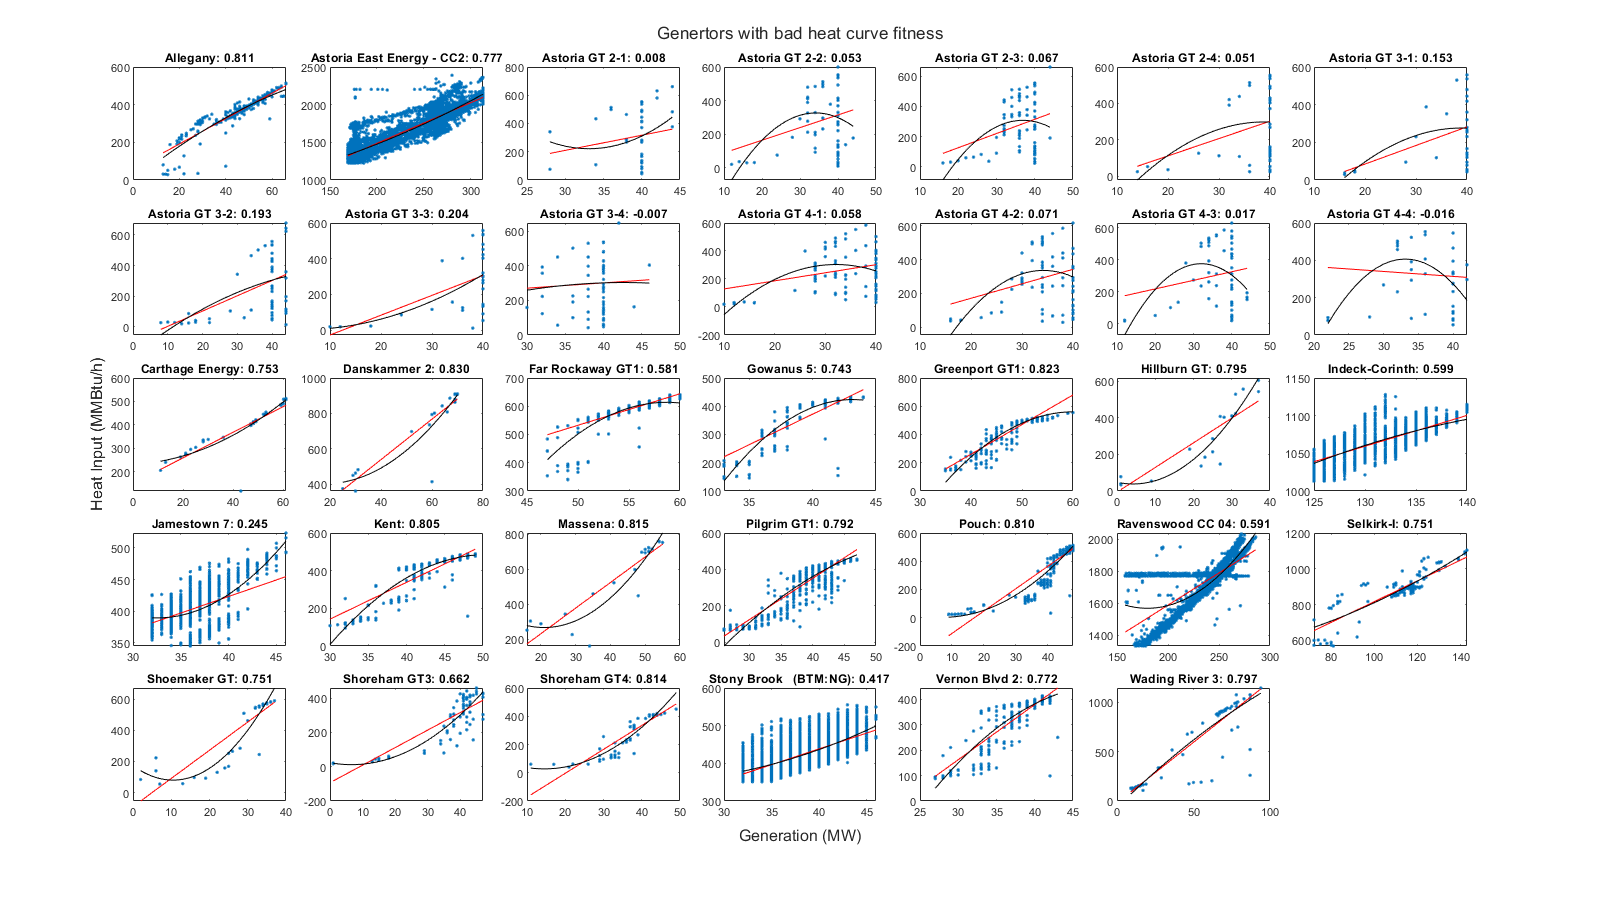

colNum = 7;
rowNum = int16(badFitNum/colNum);
t = tiledlayout(rowNum, colNum, "TileSpacing","compact");
for n=1:badFitNum
    nexttile;
    badFitName = badFitNames(n);
    badFitLMR2 = badFitLMR2s(n);
    badFitTable = badFitFilteredTables{n};
    badFitLMCoef = badFitLMCoefs(n, :);
    badFitQMCoefQM = badFitQMCoefs(n, :);
    scatter(badFitTable.sum_GrossLoadMW, badFitTable.sum_HeatInputMMBtu, '.');
    hold on;
    generation = min(badFitTable.sum_GrossLoadMW): max(badFitTable.sum_GrossLoadMW);
    plot(generation, badFitLMCoef(1) + badFitLMCoef(2).*generation, 'r-');
    plot(generation, badFitQMCoefQM(1) + badFitQMCoefQM(2).*generation + badFitQMCoefQM(3).*generation.^2, 'k-');
    hold off; box on;
    txt = sprintf("%s: %.3f", badFitName, badFitLMR2);
    title(txt);
end
xlabel(t, "Generation (MW)");
ylabel(t, "Heat Input (MMBtu/h)");
title(t, "Genertors with bad heat curve fitness");

set(gcf, "Position", [50, 50, 1600, 900]);

badAllIdx = (badFitGenJoint.LMR2) <= 0.7 | (badFitGenJoint.QMR2 <= 0.7);
gt100Idx = badFitGenJoint.maxPower >= 100;
% Subset bad fit table
badFitGt100Bad = badFitGenJoint((badAllIdx) & (gt100Idx), :) % Large CC， not sure what to do, use fitted function for now

badFitGt100Bad = 2×10 table
       NYISOName         LMR2       QMR2         UnitType        FuelType      Zone    NamePlateRatingMW    maxPower    minPower    maxRamp60
    ________________    _______    _______    ______________    ___________    ____    _________________    ________    ________    _________

    Ravenswood CC 04    0.59061    0.65822    Combined Cycle    Natural Gas     J             250             286         158          138   
    Indeck-Corinth      0.59871     0.6013    Combined Cycle    Natural Gas     F             147             140         125           20   


badFitLt100Bad = badFitGenJoint((badAllIdx) & (~gt100Idx), :) % Small JE and CT, treat as direct ramp units

badFitLt100Bad = 16×10 table
          NYISOName              LMR2         QMR2            UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower    maxRamp60
    ______________________    __________    _________    __________________    ___________    ____    _________________    ________    ________    _________

    Astoria GT 4-4             -0.015534      0.21129    Jet Engine            Kerosene        J            46.5              42         21.2          20   
    Astoria GT 3-4            -0.0072767    -0.016014    Jet Engine            Kerosene        J            46.5              46         29.4          21   
  

badFitGt100LM = badFitGenJoint((~badAllIdx) & gt100Idx, :) % Not to bad, still use fitted function

badFitGt100LM = 2×10 table
            NYISOName             LMR2       QMR2         UnitType        FuelType      Zone    NamePlateRatingMW    maxPower    minPower    maxRamp60
    _________________________    _______    _______    ______________    ___________    ____    _________________    ________    ________    _________

    Selkirk-I                    0.75148    0.75546    Combined Cycle    Natural Gas     F            107.2            143          72            63  
    Astoria East Energy - CC2    0.77719    0.77886    Combined Cycle    Natural Gas     J              320            313         169         159.5  


badFitLt100LM = badFitGenJoint((~badAllIdx) & (~gt100Idx), :) % Not to bad, still use fitted function

badFitLt100LM = 14×10 table
       NYISOName        LMR2       QMR2           UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower    maxRamp60
    _______________    _______    _______    __________________    ___________    ____    _________________    ________    ________    _________

    Gowanus 5          0.74343    0.85874    Combustion Turbine    Natural Gas     J               47             44           33          24   
    Shoemaker GT       0.75115    0.87043    Jet Engine            Natural Gas     G             41.9             37          1.5          22   
    Carthage Energy    0.75345    0.77375    Combin

## Modify parameter table due to bad fitting

needChangeNames = badFitLt100Bad.NYISOName;
needChangeIdx = ismember(paramSummaryJoint.NYISOName, needChangeNames);
noChangeParams = paramSummaryJoint(~needChangeIdx, :);
needChangeParams = paramSummaryJoint(needChangeIdx, :);

% Set min power as zero
% Set max hourly ramp rate as max power (instant ramp to maximum)
needChangeParams.minPower = zeros(size(needChangeNames));
needChangeParams.maxRampAgc = needChangeParams.maxPower./60;
needChangeParams.maxRamp10 = needChangeParams.maxPower./6;
needChangeParams.maxRamp30 = needChangeParams.maxPower./2;
needChangeParams.maxRamp60 = needChangeParams.maxPower;
% 1 MMBtu = 0.293 MWh, assume 25% efficiency, resulting 13.652 MMBtu/MWh
% EIA 2019 GT: 11098 Btu/kWh = 11.098 MMBtu/MWh
needChangeParams.HeatRateLM = repmat([0, 13.652], size(needChangeNames, 1), 1);
needChangeParams.HeatRateLMR2 = zeros(size(needChangeNames));
needChangeParams.HeatRateQM = zeros(size(needChangeNames, 1), 3);
needChangeParams.HeatRateQMR2 = zeros(size(needChangeNames));

paramSummaryFinal = [noChangeParams; needChangeParams]

paramSummaryFinal = 141×17 table
            NYISOName                 UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower    maxRampAgc    maxRamp10    maxRamp30    maxRamp60        HeatRateLM        HeatRateLMR2                 HeatRateQM                  HeatRateQMR2    CapabilitySummerMW    CapabilityWinterMW
    _________________________    __________________    ___________    ____    _________________    ________    ________    __________    _________    _________    _________    

## Get mpc.gen matrix output

busArray = [1; 2; 3; 4; 5; 6; 7; 8; 9; 10; 11];
zoneArray = categorical(["A"; "B"; "C"; "D"; "E"; "F"; "G"; "H"; "I"; "J"; "K"]);
mpcGenM = zeros(size(NYISONames, 1), 21);

for i=1:size(NYISONames, 1)
    for j=1:size(busArray, 1)
        if zoneArray(j) == paramSummaryFinal.Zone(i)        
            busID = busArray(j);
        end
    end
    mpcGenM(i, 1) = busID; % bus ID
end
mpcGenM(:, 2) = zeros(size(NYISONames)); % Pg
mpcGenM(:, 3) = zeros(size(NYISONames)); % Qg
mpcGenM(:, 4) = 9999*ones(size(NYISONames)); % Qmax
mpcGenM(:, 5) = -9999*ones(size(NYISONames)); % Qmin
mpcGenM(:, 6) = 1.00*ones(size(NYISONames)); % Vg
mpcGenM(:, 7) = 100*ones(size(NYISONames)); % mBase
mpcGenM(:, 8) = 1*ones(size(NYISONames)); % Status
mpcGenM(:, 9) = paramSummaryFinal.maxPower; % Pmax
mpcGenM(:, 10) = paramSummaryFinal.minPower; % Pmin
% 11-16 all zeros: Pc1, Pc2, Qc1min, Qc1max, Qc2min, Qc2max
mpcGenM(:, 17) = paramSummaryFinal.maxRampAgc; % ramp_agc
mpcGenM(:, 18) = paramSummaryFinal.maxRamp10; % ramp_10
mpcGenM(:, 19) = paramSummaryFinal.maxRamp30; % ramp_30
% 20-21 all zeros: ramp_q, apf
mpcGenM

mpcGenM =             2            0            0         9999        -9999            1          100            1           66           13            0            0            0            0            0            0      0.54167       5.4167        16.25            0            0
           10            0            0         9999        -9999            1          100            1          349           96            0            0            0            0            0            0         2.85         28.5         85.5            0            0
           10            0            0         9999        -9999            1          100            1          539            1            0            0            0            0            0            0       3.1083       31.083        93.25            0            0
           10            0            0         9999        -9999            1          100            1          153            1            0            0            

## Calcualte generation cost

% Need to update the prices
coalPrice = 3.663;
NGPrice = 4.922;
FOPrice = 18.664;
KSPrice = 18.664;
costLM = zeros(size(NYISONames, 1), 2);
for i=1:size(NYISONames)
    fuel = paramSummaryFinal(i, :).FuelType;
    heatRateLM = paramSummaryFinal(i, :).HeatRateLM;
    if fuel == "Coal"
        costLM(i, :) = coalPrice * heatRateLM;
    elseif fuel == "Natural Gas"
        costLM(i, :) = NGPrice * heatRateLM;
    elseif fuel == "Fuel Oil"
        costLM(i, :) = FOPrice * heatRateLM;
    elseif fuel == "Kerosene"
        costLM(i, :) = KSPrice * heatRateLM;
    else
        disp("Error!");
    end
end
paramSummaryFinal.CostLM = costLM;
paramSummaryFinal

paramSummaryFinal = 141×18 table
            NYISOName                 UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower    maxRampAgc    maxRamp10    maxRamp30    maxRamp60        HeatRateLM        HeatRateLMR2                 HeatRateQM                  HeatRateQMR2    CapabilitySummerMW    CapabilityWinterMW          CostLM      
    _________________________    __________________    ___________    ____    _________________    ________    ________    __________    _________    _________

## Get mpc.gencost matrix output

mpcGenCostM = zeros(size(NYISONames, 1), 6);
mpcGenCostM(:, 1) = 2*ones(size(NYISONames)); % Cost Model
mpcGenCostM(:, 2) = zeros(size(NYISONames)); % Startup cost
mpcGenCostM(:, 3) = zeros(size(NYISONames)); % Shutdown cost
mpcGenCostM(:, 4) = 2*ones(size(NYISONames)); % number of parameters: linear=2
mpcGenCostM(:, 5:6) = paramSummaryFinal.CostLM;
mpcGenCostM

mpcGenCostM =             2            0            0            2       278.37       33.187
            2            0            0            2       1236.7       42.596
            2            0            0            2         1890       42.763
            2            0            0            2       737.57       52.645
            2            0            0            2       4701.8       84.075
            2            0            0            2       5101.6       82.018
            2            0            0            2       1919.5       25.005
            2            0            0            2       1733.1       25.702
            2            0            0            2       1155.2       28.738
            2            0            0            2       2005.1       26.568


## Write gen matrix to file

save("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\MGen.mat", "mpcGenM", "-mat");
save("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\MGenCost.mat", "mpcGenCostM", "-mat");
save("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\MParamSummary.mat", "paramSummaryFinal", "-mat");